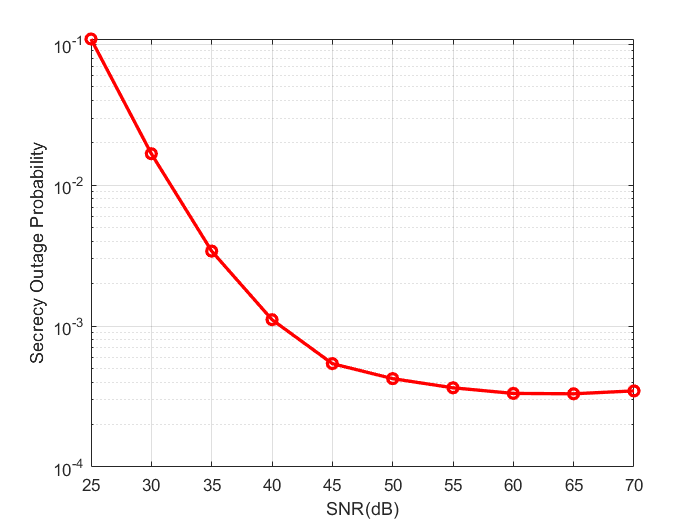

%NaNA会议
TargetCapacity=1;
Loop=1e6;
loss=3;
radius=50;
%K=4;
%K=5;
%K=6;
K=3;
Length=1;
%length=3;
%length=5;
%Length=[1;2;3;4;5;6;7;8;9;10];%探究缓冲区长度对安全性能的影响
FaithDegree=[1;0.8;0.6];
%FaithDegree=[1;1;0.5;0.4;0.3];
%FaithDegree=[0.5;0.8;0.6];%探究信任度对性能的影响
%power=sqrt(1e10);%功率SNR取50
%x=[1;2;3;4;5;6;7;8;9;10];%探究缓冲区长度对安全性能的影响
power=[sqrt(1e5);1e3;sqrt(1e7);1e4;sqrt(1e9);1e5;sqrt(1e11);1e6;sqrt(1e13);1e7];
%power=1e5;
x=[25;30;35;40;45;50;55;60;65;70];
capacity=zeros(1,1);
out=zeros(10,1);%发生中断次数
probability=zeros(10,1);%保密中断概率

%E=InitEavesLocation(radius);%初始化窃听节点位置
distance=InitRelayLocation(K,radius);%初始中继位置
E=[42.2951488680842	4.64407549039650];
distance(1,:)=[1.25394419843626	0.325530616980935	51.1896593729494	48.8135588273074];
    distance(2,:)=[15.2597178673075	0.198297702741642	65.0301994770073	35.1680413836239];
    distance(3,:)=[9.49676363513545	0.624473127745221	57.9709727112111	42.6584500655999];
RelayNode=InitRelayNode(K);
SR_Link=InitSRLink(K);
RD_Link=InitRDLink(K);
SE_Link=InitSELink(E,radius);
RE_Link=InitRELink(K,distance,E);
for i=1:10
    for j=1:Loop
        RelayNode=UpdateFaith(K,FaithDegree,RelayNode);
        [SR_Link,RD_Link]=UpdateMainChannel(SR_Link,RelayNode,RD_Link,K,distance,loss);
        SE_Link=UpdateSEChannel(SE_Link,loss);
        RE_Link=UpdateREChannel(RE_Link,K,loss);
        [m,state]=SelectTransmissionNode(SR_Link,RD_Link);
        [capacity,flag]=CalCapacity(m,state,power(i,1),SR_Link,RD_Link,SE_Link,RE_Link,TargetCapacity);
        %探究功率对安全性能的影响
        %[capacity,flag]=CalCapacity(m,state,power,SR_Link,RD_Link,SE_Link,RE_Link,TargetCapacity);
        if(flag==1)
           [SR_Link,RelayNode,RD_Link]=TransmissionData(m,state,SR_Link,RelayNode,RD_Link,Length);
          %[SR_Link,RelayNode,RD_Link]=TransmissionData(m,state,SR_Link,RelayNode,RD_Link,Length(i,1));
            %探究缓冲区长度对安全性能的影响
        else
            out(i,1)=out(i,1)+1;
        end
    end
    probability(i,1)=out(i,1)/Loop;
end
semilogy(x,probability,'-or','LineWidth',2);     
%title('New Max-Ratio');
xlabel('SNR(dB)');
ylabel('Secrecy Outage Probability');
grid on